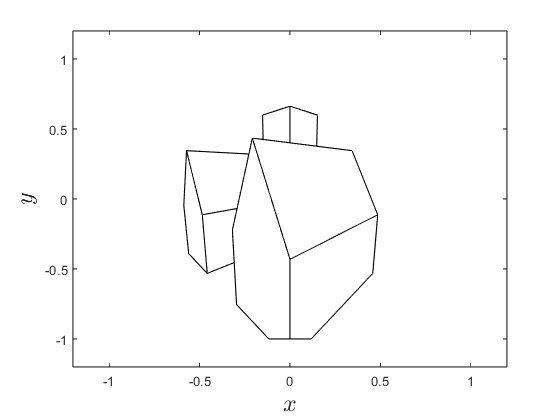

clear

% Load screen space coordinates
load('front_facing_coordinates.mat')

% Apply painter's algorithm to order face matrix
Fpainters = painters(Vclipped, Ffront, [0;0;1]);

% Plot front facing polygons space (from viewing position)
hold on
for i = 1 : size(Fpainters, 1)
    x = zeros(1, size(Fpainters,2));
    y = zeros(1, size(Fpainters,2));
    for j = 1 : size(Fpainters, 2)
        x(j) = Vclipped(1,Fpainters(i,j));
        y(j) = Vclipped(2,Fpainters(i,j));
    end
    fill(x, y, 'w')
end
hold off
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

exportgraphics(gcf,'../images/painters_example.png','Resolution',300) 

function Fpainter = painters(V, F, p)

z = 1e4 * ones(size(F, 1), 1);
for i = 1 : size(F, 1)
    for j = 1 : size(F, 2)
        z(i) = min(z(i), norm(V(1:3,F(i,j)) - p));
    end
end

[~, idx] = sort(z, 'descend');
Fpainter = F(idx, :);

end